# Distributions of beat period, flagellum length, and maximum distal curvature (MDC)

This live MATLAB script reproduces Fig. 5 from Walker BJ, Phuyal S, Ishimoto K, Tung C-K, Gaffney EA. (2020) Computer-assisted beat-pattern analysis and the flagellar waveforms of bovine spermatozoa. R. Soc. Open Sci. 7: 200769.

Histograms of the beat period, flagellum length, and maximal distal curvature are plotted. When two samples are compared, the probability that the samples in question are drawn from the same probability distribution (i.e. the p value of the Kolmogorov-Smirnov test) is also displayed.

addpath('.\Data',  '.\Functions',  '.\Images',  '.\Movies')
load periods.mat
load arclengths.mat
load tip_curvs.mat
load swimmingspeeds.mat
load masks.mat

bleb_periods = B_periods(find(bleb_mask == 1) - 79);
unbleb_periods = B_periods(find(unbleb_mask == 1) - 79);
bleb_arclengths = B(find(bleb_mask == 1) - 79);
unbleb_arclengths = B(find(unbleb_mask == 1) - 79);
bleb_curvs = B_curvs(find(bleb_mask == 1) - 79);
unbleb_curvs = B_curvs(find(unbleb_mask == 1) - 79);


## Data for individual sperm

For which sperm do you wish to display the beat period, flagellum length, and MDC? 

[Select an integer from 1 to 216]

spermid = 3;
period = data{spermid}.period; 
arclength = data{spermid}.flagellum_length;

% % The wavenumber and phase come from a nonlinear fit of the mean of all cell_coeff(:,:,1).
% ft = fittype( {'1', '(cos(0.8901*x-2.574))'}, 'independent', 'x', 'dependent', 'y', 'coefficients', {'a', 'b'} );
% ts = (1:100)' * (2*pi/100);
% % Fit model to data.
% for i = spermid
% 	f = fit(ts, cell_coeff(:,i), ft);
% 	Const = f.a;
% 	Cosine = f.b;
% end

%here we compute MDC. Curvature = theta'(s); MDC = max abs curvature over
%distal 10%
tangentangle = data{spermid}.tangent_angle(:,:);
curvature = (tangentangle(:,901:1000) - tangentangle(:,900:999))*999;
MDC = max(max(abs(curvature)))/arclength;
% if spermid <= 79
%     vbar = A_speeds(spermid);
% else
%     vbar = B_speeds(spermid - 1);
% end
disp(['period = ' num2str(period) ' s']);

period = 0.24215 s


disp(['flagellum length = ' num2str(arclength) ' μm']);

flagellum length = 59.9323 μm


disp(['Maximal distal curvature = ' num2str(MDC) ' μm^{-1}']);

Maximal distal curvature = 0.24141 μm^{-1}


% disp(['average swimming speed = ' num2str(vbar) ' μm^{-1}'])
% disp(['alpha = ' num2str(Const) ' s']);
% disp(['beta = ' num2str(Cosine) ' s']);



## Histogram of beat periods

Which sample do you wish to plot?

KS p value: 2.7657e-21


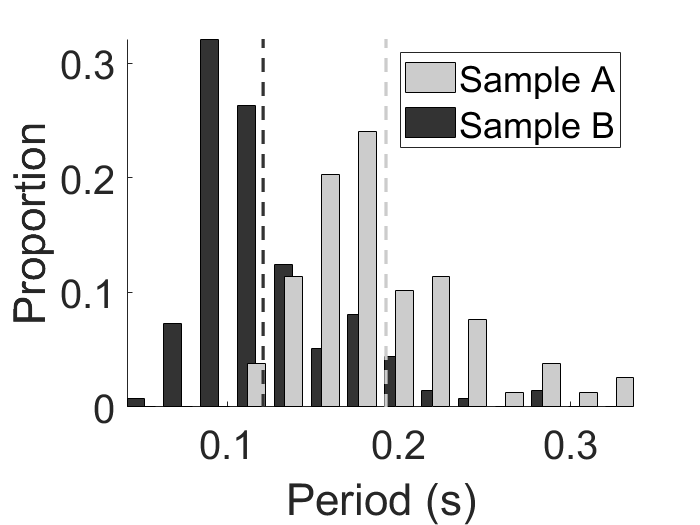

sample = 3;


if sample == 3
%     close all
%     figure
% subplot(3,1,1)
figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([A_periods,B_periods]);
maxx = max([A_periods,B_periods]);
edges = linspace(0.05,0.35,15);
hA = histcounts(A_periods,edges,'Normalization','probability');
hB = histcounts(B_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_periods),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(B_periods),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Period (s)')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'Sample A','Sample B'})
set(gca,'XTick',[0.1,0.2,0.3])
[h,p] = kstest2(A_periods,B_periods);
disp(['KS p value: ',num2str(p)])
print('periods.eps','-depsc')

elseif sample == 1
    
    %     close all
    figure
% subplot(3,1,1)
figure
hold on
A_col = 0.8;
minx = min([A_periods]);
maxx = max([A_periods]);
edges = linspace(0.05,0.35,15);
hA = histcounts(A_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA,'BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_periods),1,2),[0,max([hA])],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('Period (s)')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'Sample A'})
set(gca,'XTick',[0.1,0.2,0.3])
% [h,p] = kstest2(A_periods,B_periods);
% disp(['KS p value: ',num2str(p)])
print('periods.eps','-depsc')

elseif sample == 2
    
    figure
hold on
B_col = 0.2;
minx = min([B_periods]);
maxx = max([B_periods]);
edges = linspace(0.05,0.35,15);
hB = histcounts(B_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B_periods),1,2),[0,max(hB)],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Period (s)')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'Sample B'})
set(gca,'XTick',[0.1,0.2,0.3])
[h,p] = kstest2(A_periods,B_periods);
% disp(['KS p value: ',num2str(p)])
print('periods.eps','-depsc')



elseif sample == 6
%     close all
%     figure
% subplot(3,1,1)
figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([bleb_periods,unbleb_periods]);
maxx = max([bleb_periods,unbleb_periods]);
edges = linspace(0.05,0.35,15);
hA = histcounts(bleb_periods,edges,'Normalization','probability');
hB = histcounts(unbleb_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_periods),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_periods),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Period (s)')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'blebbed','unblebbed'})
set(gca,'XTick',[0.1,0.2,0.3])
[h,p] = kstest2(bleb_periods,unbleb_periods);
disp(['KS p value: ',num2str(p)])
print('periods.eps','-depsc')

% xlim([-0.124 0.171])
% ylim([0.296 0.649])

elseif sample == 4
    %     close all
    figure
% subplot(3,1,1)
figure
hold on
A_col = 0.8;
minx = min([bleb_periods]);
maxx = max([bleb_periods]);
edges = linspace(0.05,0.35,15);
hA = histcounts(bleb_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA,'BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_periods),1,2),[0,max([hA])],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('Period (s)')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'blebbed'})
set(gca,'XTick',[0.1,0.2,0.3])
% [h,p] = kstest2(A_periods,B_periods);
% disp(['KS p value: ',num2str(p)])
print('periods.eps','-depsc')

elseif sample == 5
    
    figure
hold on
B_col = 0.2;
minx = min([unbleb_periods]);
maxx = max([unbleb_periods]);
edges = linspace(0.05,0.35,15);
hB = histcounts(unbleb_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_periods),1,2),[0,max(hB)],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Period (s)')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'unblebbed'})
set(gca,'XTick',[0.1,0.2,0.3])
[h,p] = kstest2(bleb_periods,unbleb_periods);
% disp(['KS p value: ',num2str(p)])
print('periods.eps','-depsc')

end

## Histogram of flagellum lengths

Which sample do you wish to plot?

KS p value: 0.00022865


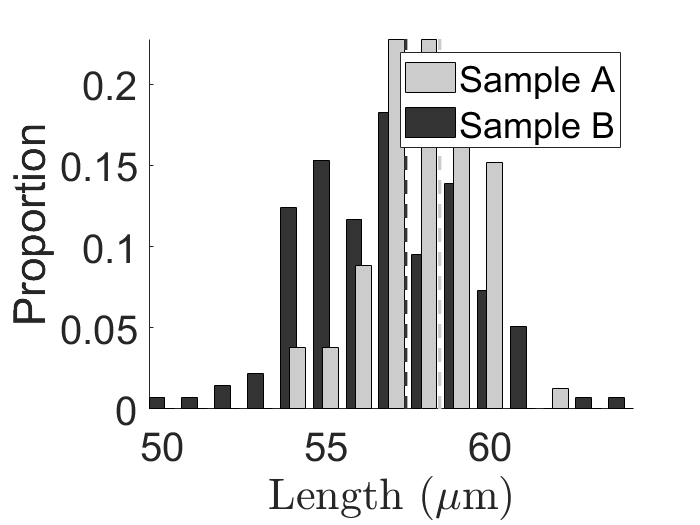

sample = 3;

if sample == 3
figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([A;B]);
maxx = max([A;B]);
edges = linspace(50,65,16);
hA = histcounts(A,edges,'Normalization','probability');
hB = histcounts(B,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(B),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Length ($\mu$m)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'Sample A','Sample B'})
[h,p] = kstest2(A,B);
disp(['KS p value: ',num2str(p)])
print('arclengths.eps','-depsc')

elseif sample == 1
 figure
hold on
A_col = 0.8;
minx = min([A]);
maxx = max([A]);
edges = linspace(50,65,16);
hA = histcounts(A,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA,'BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A),1,2),[0,max(hA)],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('Length ($\mu$m)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend(b(1),{'Sample A'})
% [h,p] = kstest2(A,B);
% disp(['KS p value: ',num2str(p)])
% print('arclengths.eps','-depsc')

elseif sample == 2
    figure
hold on
% % A_col = 0.8;
B_col = 0.2;
minx = min([B]);
maxx = max([B]);
edges = linspace(50,65,16);
hB = histcounts(B,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Length ($\mu$m)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend(b(1),{'Sample B'})
% [h,p] = kstest2(A,B);
% disp(['KS p value: ',num2str(p)])
print('arclengths.eps','-depsc')

elseif sample == 6
figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([bleb_arclengths;unbleb_arclengths]);
maxx = max([bleb_arclengths;unbleb_arclengths]);
edges = linspace(50,65,16);
hA = histcounts(bleb_arclengths,edges,'Normalization','probability');
hB = histcounts(unbleb_arclengths,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_arclengths),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_arclengths),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Length ($\mu$m)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'blebbed','unblebbed'})
[h,p] = kstest2(bleb_arclengths,unbleb_arclengths);
disp(['KS p value: ',num2str(p)])
print('arclengths.eps','-depsc')

elseif sample == 4
    
    
% subplot(3,1,2)
figure
hold on
A_col = 0.8;
minx = min([bleb_arclengths]);
maxx = max([bleb_arclengths]);
edges = linspace(50,65,16);
hA = histcounts(bleb_arclengths,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA,'BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_arclengths),1,2),[0,max(hA)],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('Length ($\mu$m)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend(b(1),{'blebbed'})
% [h,p] = kstest2(A,B);
% disp(['KS p value: ',num2str(p)])
% print('arclengths.eps','-depsc')

elseif sample == 5
    figure
hold on
% % A_col = 0.8;
B_col = 0.2;
minx = min([unbleb_arclengths]);
maxx = max([unbleb_arclengths]);
edges = linspace(50,65,16);
hB = histcounts(unbleb_arclengths,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_arclengths),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Length ($\mu$m)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend(b(1),{'unblebbed'})
% [h,p] = kstest2(A,B);
% disp(['KS p value: ',num2str(p)])
print('arclengths.eps','-depsc')
    

end

## Histogram of MDCs

Which sample do you wish to plot?

KS p value: 0.57586


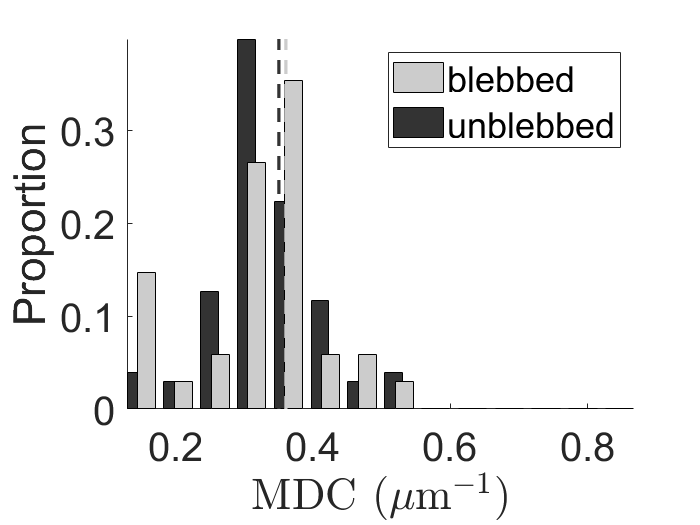

sample = 6;

% subplot(3,1,3)
if sample == 3

figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([A_curvs;B_curvs]);
maxx = max([A_curvs;B_curvs]);
edges = linspace(0.15,0.9,15);
hA = histcounts(A_curvs,edges,'Normalization','probability');
hB = histcounts(B_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_curvs),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(B_curvs),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('MDC ($\mu$m$^{-1}$)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'Sample A','Sample B'})
[h,p] = kstest2(A_curvs,B_curvs);
disp(['KS p value: ',num2str(p)])
print('max_tip_curv.eps','-depsc')


elseif sample == 1



% subplot(3,1,3)
figure
hold on
A_col = 0.8;
minx = min([A_curvs]);
maxx = max([A_curvs]);
edges = linspace(0.15,0.9,15);
hA = histcounts(A_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hA]','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_curvs),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('MDC ($\mu$m$^{-1}$)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight


elseif sample == 2
    
    
figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([B_curvs]);
maxx = max([B_curvs]);
edges = linspace(0.15,0.9,15);
hB = histcounts(B_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B_curvs),1,2),[0,max([hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('MDC ($\mu$m$^{-1}$)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'Sample B'})
% [h,p] = kstest2(B_curvs);
% disp(['KS p value: ',num2str(p)])
print('max_tip_curv.eps','-depsc')

elseif sample == 6

figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([bleb_curvs;unbleb_curvs]);
maxx = max([bleb_curvs;unbleb_curvs]);
edges = linspace(0.15,0.9,15);
hA = histcounts(bleb_curvs,edges,'Normalization','probability');
hB = histcounts(unbleb_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_curvs),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_curvs),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('MDC ($\mu$m$^{-1}$)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'blebbed','unblebbed'})
[h,p] = kstest2(bleb_curvs,unbleb_curvs);
disp(['KS p value: ',num2str(p)])
print('max_tip_curv.eps','-depsc')


elseif sample == 4



figure
hold on
A_col = 0.8;
minx = min([bleb_curvs]);
maxx = max([bleb_curvs]);
edges = linspace(0.15,0.9,15);
hA = histcounts(bleb_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hA]','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_curvs),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('MDC ($\mu$m$^{-1}$)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'blebbed'})


elseif sample == 5
    
    
figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([unbleb_curvs]);
maxx = max([unbleb_curvs]);
edges = linspace(0.15,0.9,15);
hB = histcounts(unbleb_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_curvs),1,2),[0,max([hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('MDC ($\mu$m$^{-1}$)','interpreter',"latex")
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'unblebbed'})

print('max_tip_curv.eps','-depsc')




end